# Lesson 5: Applying Color Filters to Images

## How to Create a Two-Tone Image with MATLAB

This script uses images from the [Pixels to Pictures](https://www.mathworks.com/academia/highschool/courseware/pixels-to-pictures.html) courseware.  Be sure to download and install this toolbox and place this script ("Create2ToneImage.mlx") in the same folder as the "Image Library" folder.  Or, feel free to change the first section (Lines 1-6) to read your own images.

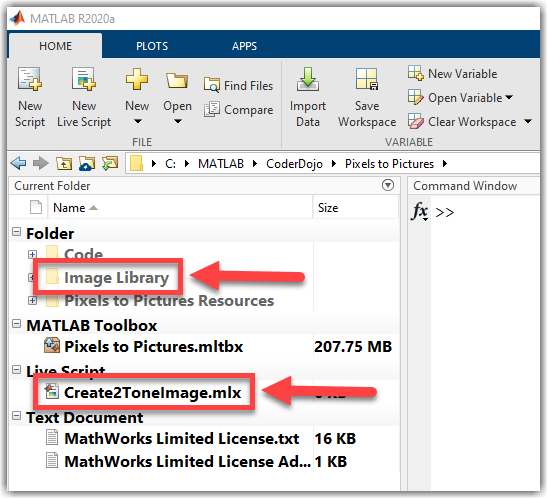

#### Load Two Images and Resize to Match

Use the drop-down menus to choose two images.  The function `fullfile` creates the full path to the image by combining the folder location and the file name.

folder = "Image Library";
file1 = "boston.jpg";
file2 = "child.jpg";

I1 = imread(fullfile(folder,file1));
I2 = imread(fullfile(folder,file2));

In order to combine these images later, we'll need to resize one of the images to match the size of the other image.  We can use the `size` function to determine the size of an image (or array).  This function returns an array with values for the size along each dimension.

sz = size(I2)

Recall, images have three dimensions: rows, columns, and pages.  So the variable `sz` contains the number of rows, the number of columns, and the number of pages, respectively.  We can then extract these values using what we previously learned about indexing.

rows = sz(1);
cols = sz(2);
I1 = imresize(I1,[rows cols]); % resize I1 to match I2
imshowpair(I1,I2,'montage')

#### Create Color Filters

We'll once again use the `newFilter` function from the [Pixels to Pictures](https://www.mathworks.com/academia/highschool/courseware/pixels-to-pictures.html) toolbox to create color filters.  In order to use these filters they must be the same size as our images.  And we'll set the RGB values of these filters to match the two colors of our 3D glasses: red and cyan (green/blue).  Recall we specify colors using Red, Green, and Blue (RGB) values, which range from 0 to 255.

red  = [255 0 0];
cyan = [0 255 255];
R = newFilter(rows,cols,red);
C = newFilter(rows,cols,cyan);
imshowpair(R,C,'montage')

#### Use Filters to Remove Opposite Color from Each Image

We'll create a cyan-tone image by filtering out all the red shades in the first image.  And then, we'll create a red-tone image by filtering out all the cyan shades in the other image.

Icyan = I1 - R;  % remove red
Ired  = I2 - C;  % remove cyan
imshowpair(Icyan,Ired,'montage')

#### Add Filtered Images Together

While wearing 3D glasses, try closing one eye at a time....

I = Ired + Icyan;
imshow(I)